# Exponential Moving Average Filter

#### Analyseos of Discrete Time Systems

h_da, fbeit, IMSE Electrical Engineering, C. Jakob, SS 2023

**History**:

- Version 1.1: Initial Version, Darmstadt, 05.06.2023,  C. Jakob 

Some clean-up and basic configurations at startup

clear all; 
clc; 
close all;

set(groot, 'defaultTextInterpreter', 'LaTeX');
set(groot, 'DefaultAxesTickLabelInterpreter', 'LaTeX');

format long; 

**Exponential Moving Average**


$$f_s = 8kHz$$
 


$$y(n)=\alpha x(n)+(1-\alpha)y(n-1)$$


Transfer Function:


$$\mathcal{Z}\{y[n]\}=\mathcal{Z}\{\alpha x(n)+(1-\alpha)y(n-1) \} 
$$
 


$$\mathcal{Z}\{y[n]\}= Y(z)=\alpha X(z) + (1-\alpha)Y(z)z^{-1} 
$$



$$\mathcal{Z}\{y[n]\}= Y(z)-(1-\alpha)Y(z)z^{-1} =\alpha X(z) 
$$



$$\mathcal{Z}\{y[n]\}= Y(z)(1-(1-\alpha)z^{-1} )=\alpha X(z) \longrightarrow H(z)=Y(z)/X(z)= \frac{\alpha}{1-(1-\alpha)z^{-1}}
$$


**Transfer Function in MATLAB**

fs = 8000;         
Ts = 1/fs;         

alpha = 0.1;

num   = [alpha];            % Koeffizienten des Zählerpolynoms (Zähler, engl. numerator) 
denom = [1,-(1-alpha)];     % Koeffizienten des Nennerpolynoms (Nenner, engl. denominator) 

**Exponential** Moving Average


$$\longrightarrow y(n-1)$$



$$y(n)=\alpha x(n)+(1-\alpha)y(n-1)$$
  


$$y(n)=\alpha x(n)+(1-\alpha)(\alpha x(n-1)+(1-\alpha)y(n-2))
$$
  


$$y(n)=\alpha x(n)+ \alpha(1-\alpha) x(n-1)+(1-\alpha)^2y(n-2)$$
  


$$\longrightarrow y(n-2)$$



$$y(n)=\alpha x(n)+ \alpha(1-\alpha) x(n-1)+(1-\alpha)^2y(n-2)$$
  


$$y(n)=\alpha x(n)+ \alpha(1-\alpha) x(n-1)+(1-\alpha)^2(\alpha x(n-2)+(1-\alpha)y(n-3))$$
  


$$y(n)=\alpha x(n)+ \alpha(1-\alpha) x(n-1)+ \alpha(1-\alpha)^2 x(n-2)+(1-\alpha)^3y(n-3))$$
  


$$\longrightarrow ...$$



$$y(n)=\alpha x(n)+ \alpha(1-\alpha) x(n-1)+ \alpha(1-\alpha)^2 x(n-2)+ \alpha(1-\alpha)^3 x(n-3) + \alpha(1-\alpha)^4x(n-4) + ...$$
  

Dieser Ausdruck lässt sich wie folg umschreiben:


$$y(n)=\alpha \bigl( x(n)+ (1-\alpha) x(n-1)+ (1-\alpha)^2 x(n-2)+ (1-\alpha)^3 x(n-3) + (1-\alpha)^4x(n-4) + ...\bigr)$$
  


$$y(n)=\alpha \sum_{k=0}^{\infty}(1-\alpha)^kx(n-k)$$
  

**Stability Check**


$$H(z)= \frac{\alpha}{1-(1-\alpha)z^{-1}} \longrightarrow H(z)= \frac{\alpha z}{z-(1-\alpha)
$$


Zero at $z=0$, Pole at $z = (1-\alpha)$  

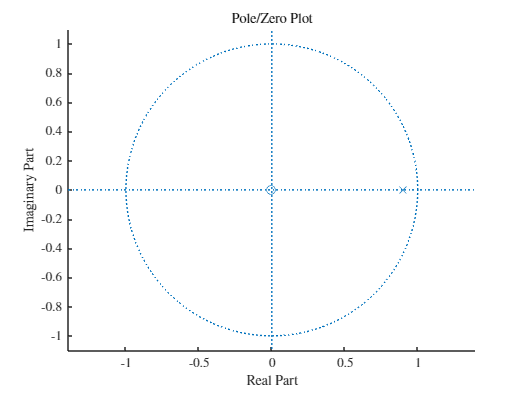

fig = figure;
set(fig,'color','w');
zplane(num,denom);
box off; 
title('Pole/Zero Plot','Interpreter','latex','FontWeight','Normal');

**Transfer Function to Frequency Response**


$$H(z)=\frac{\alpha}{1-(1-\alpha)z^{-1}} \longrightarrow H(z)| {z=e^{j \omega T_s}} = H(e^{j \omega T_s})=\frac{\alpha}{1-(1-\alpha) e^{-j \omega T_s}}
$$


MATLAB: **freqz**: 

f_points = 1000;                        
[H, f]   = freqz(num,denom,f_points,fs);       

In general


$$z(\omega)  = \frac{z_1(\omega) }{z_2(\omega) }=\frac{a(\omega) +jb(\omega) }{c(\omega) +jd(\omega) } \longrightarrow \left|z(\omega) \right|=\frac{\left| z_1(\omega)  \right|}{\left| z_2(\omega)  \right|}$$


**Amplitude Response**


$$| H(e^{j \omega T_s})|= \Biggl| \frac{\alpha}{1-(1-\alpha) e^{-j \omega T_s}} \Biggr|
$$



$$| H(e^{j \omega T_s})|= \frac{\left| \alpha \right|}{\left|1-(1-\alpha) e^{-j \omega T_s} \right|} = \frac{\left| \alpha \right|}{\left|1-(1-\alpha)cos(\omega T_s)+j(1-\alpha)sin(\omega T_s) \right|}}
$$



$$| H(e^{j \omega T_s})|= \frac{\alpha}{\sqrt{(1-(1-\alpha)cos(\omega T_s))^2+((1-\alpha)sin(\omega T_s))^2 }}}
$$



$$| H(e^{j \omega T_s})|= \frac{\alpha}{\sqrt{(1-2(1-\alpha)cos(\omega T_s) +(1-\alpha)^2cos^2(\omega T_s)+(1-\alpha)^2sin^2(\omega T_s)}
$$



$$| H(e^{j \omega T_s})|= \frac{\alpha}{\sqrt{(1-2(1-\alpha)cos(\omega T_s) +(1-\alpha)^2(cos^2(\omega T_s)+sin^2(\omega T_s))}
$$



$$| H(e^{j \omega T_s})|= \frac{\alpha}{\sqrt{(1-2(1-\alpha)cos(\omega T_s) +(1-\alpha)^2 }
$$


Plot the magnitude response

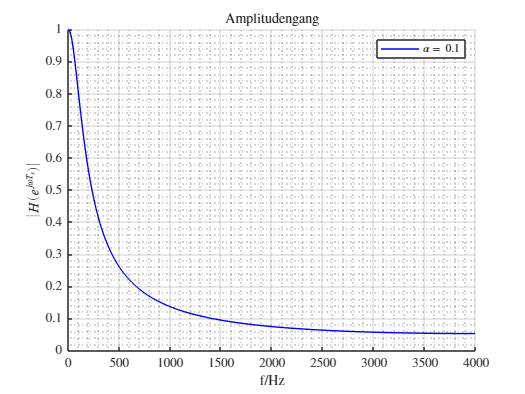

H_abs = alpha./sqrt(1-2*(1-alpha)*cos(2*pi*f*Ts)+(1-alpha)^2);

fig = figure;
set(fig,'color','w');
plot(f,H_abs,'color','blue');                         
grid on; grid minor;
box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$\left| H(e^{j\omega T_s}) \right|$','Interpreter','latex');
title('Amplitudengang','Interpreter','latex','FontWeight','Normal');
legend(['$\alpha =$',' ',num2str(alpha)],'Interpreter','latex');

MATLAB related magnitude response computation: 

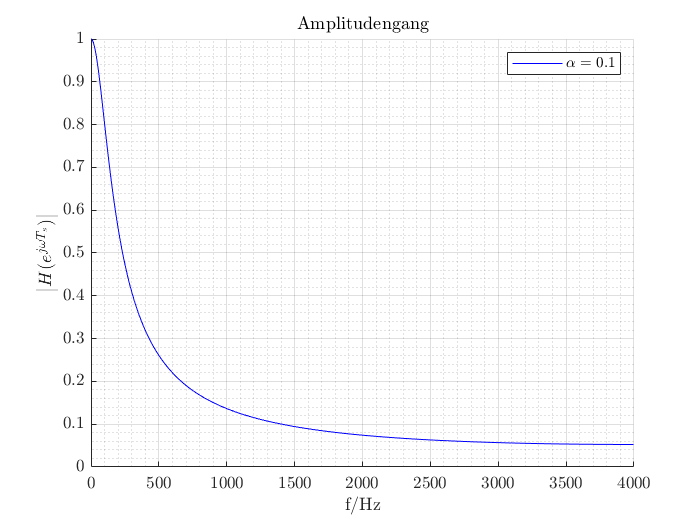

fig = figure;
set(fig,'color','w');
plot(f,abs(H),'color','blue');                         
grid on; grid minor;
box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$\left| H(e^{j\omega T_s}) \right|$','Interpreter','latex');
title('Amplitudengang','Interpreter','latex','FontWeight','Normal');
legend(['$\alpha =$',' ',num2str(alpha)],'Interpreter','latex');

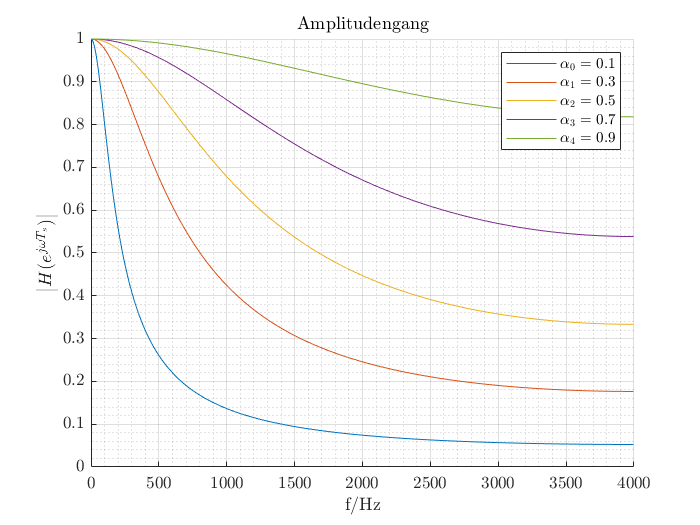

alpha_0 = 0.1;
alpha_1 = 0.3;
alpha_2 = 0.5;
alpha_3 = 0.7;
alpha_4 = 0.9;

H_abs_0 = alpha_0./sqrt(1-2*(1-alpha_0)*cos(2*pi*f*Ts)+(1-alpha_0)^2);
H_abs_1 = alpha_1./sqrt(1-2*(1-alpha_1)*cos(2*pi*f*Ts)+(1-alpha_1)^2);
H_abs_2 = alpha_2./sqrt(1-2*(1-alpha_2)*cos(2*pi*f*Ts)+(1-alpha_2)^2);
H_abs_3 = alpha_3./sqrt(1-2*(1-alpha_3)*cos(2*pi*f*Ts)+(1-alpha_3)^2);
H_abs_4 = alpha_4./sqrt(1-2*(1-alpha_4)*cos(2*pi*f*Ts)+(1-alpha_4)^2);

fig = figure;
set(fig,'color','w');
plot(f,H_abs_0);     
hold on;
plot(f,H_abs_1);     
hold on;
plot(f,H_abs_2);     
hold on;
plot(f,H_abs_3);     
hold on;
plot(f,H_abs_4);     
hold on;
grid on; grid minor;
box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$\left| H(e^{j\omega T_s}) \right|$','Interpreter','latex');
title('Amplitudengang','Interpreter','latex','FontWeight','Normal');
legend(['$\alpha_0 =$',' ',num2str(alpha_0)],...
       ['$\alpha_1 =$',' ',num2str(alpha_1)],...
       ['$\alpha_2 =$',' ',num2str(alpha_2)],...
       ['$\alpha_3 =$',' ',num2str(alpha_3)],...
       ['$\alpha_4 =$',' ',num2str(alpha_4)],...
       'Interpreter','latex');

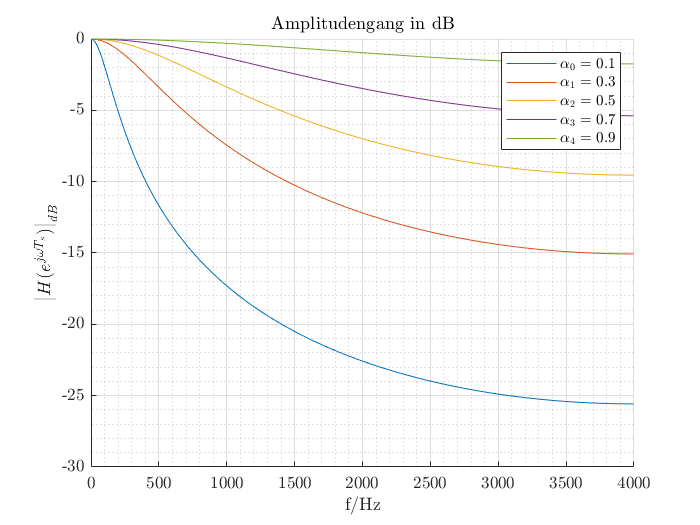

fig = figure;
set(fig,'color','w');
plot(f,mag2db(H_abs_0));     
hold on;
plot(f,mag2db(H_abs_1));     
hold on;
plot(f,mag2db(H_abs_2));     
hold on;
plot(f,mag2db(H_abs_3));     
hold on;
plot(f,mag2db(H_abs_4));     
hold on;
grid on; grid minor;
box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$\left| H(e^{j\omega T_s}) \right|_{dB}$','Interpreter','latex');
title('Amplitudengang in dB','Interpreter','latex','FontWeight','Normal');
legend(['$\alpha_0 =$',' ',num2str(alpha_0)],...
       ['$\alpha_1 =$',' ',num2str(alpha_1)],...
       ['$\alpha_2 =$',' ',num2str(alpha_2)],...
       ['$\alpha_3 =$',' ',num2str(alpha_3)],...
       ['$\alpha_4 =$',' ',num2str(alpha_4)],...
       'Interpreter','latex');

**Phase response calculation**


$$z(\omega) = \frac{z_1(\omega)}{z_2(\omega)}=\frac{a(\omega)+jb(\omega)}{c(\omega)+jd(\omega)} \longrightarrow \left|z(\omega)\right|=\frac{\left| z_1(\omega) \right|}{\left| z_2(\omega) \right|}, \quad \angle\; z(\omega) = \angle\;z_1(\omega) - \angle\;z_2(\omega)=tan^{-1}(b(\omega)/a(\omega))-tan^{-1}(d(\omega)/c(\omega))$$



$$H(e^{j \omega T_s})= \frac{z_1(\omega)}{z_2(\omega)}=\frac{\alpha}{1-(1-\alpha) e^{-j \omega T_s}}
$$



$$\angle\;z_1(\omega) =tan^{-1}(0/\alpha)=0$$



$$1-(1-\alpha) e^{-j \omega T_s} = 1-(1-\alpha)cos(\omega T_s)+j(1-\alpha)sin(\omega T_s) }}
$$



$$\angle\;z_2(\omega) =tan^{-1} \biggl( \frac{(1-\alpha)sin(\omega T_s)}{1-(1-\alpha)cos(\omega T_s)} \biggr)$$



$$\angle\;H(e^{j \omega T_s})= -tan^{-1} \biggl( \frac{(1-\alpha)sin(\omega T_s)}{1-(1-\alpha)cos(\omega T_s)} \biggr)$$


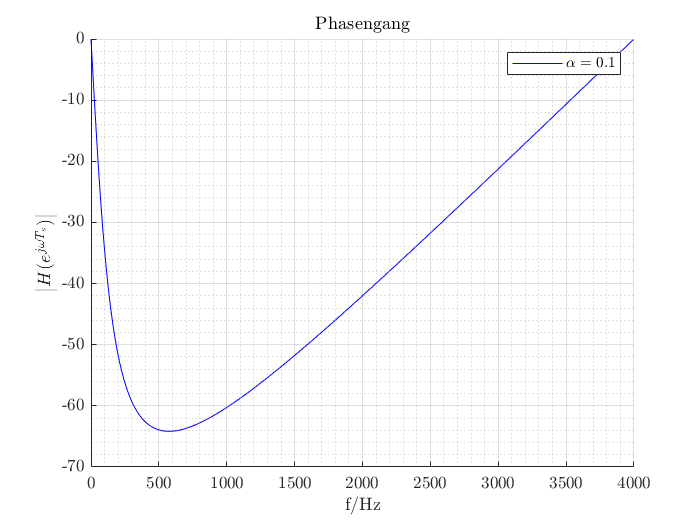

phase = -1*atan(((1-alpha)*sin(2*pi*f*Ts))./(1-(1-alpha)*cos(2*pi*f*Ts)))*180/pi;

fig = figure;
set(fig,'color','w');
plot(f,phase,'color','blue');                         
grid on; grid minor;
box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$\left| H(e^{j\omega T_s}) \right|$','Interpreter','latex');
title('Phasengang','Interpreter','latex','FontWeight','Normal');
legend(['$\alpha =$',' ',num2str(alpha)],'Interpreter','latex');

Phase response in MATLAB::

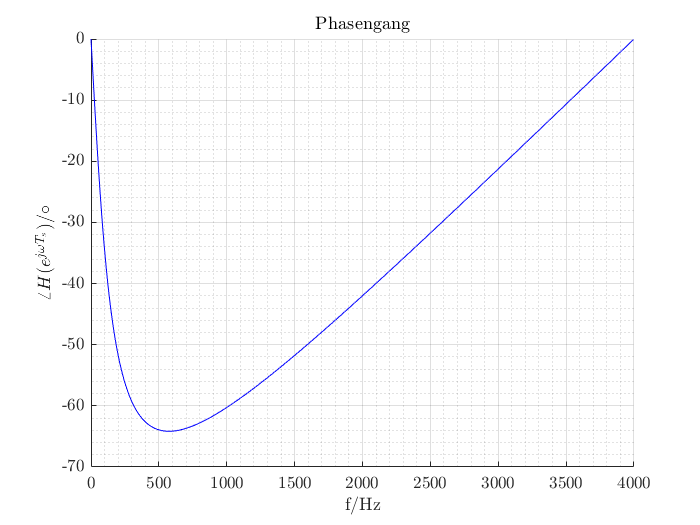

fig = figure;
set(fig,'color','w');
plot(f,angle(H)*180/pi,'color','blue');       
grid on; grid minor;
box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$ \angle H(e^{j\omega T_s})/ {\circ} $','Interpreter','latex');
title('Phasengang','Interpreter','latex','FontWeight','Normal');

 Beide Vorgehen führen zu identischen Resultaten. Nachfolgend soll der Amplitudengang für unterschiedliche Werte für $\alpha$ berechnet und dargestellt werden.

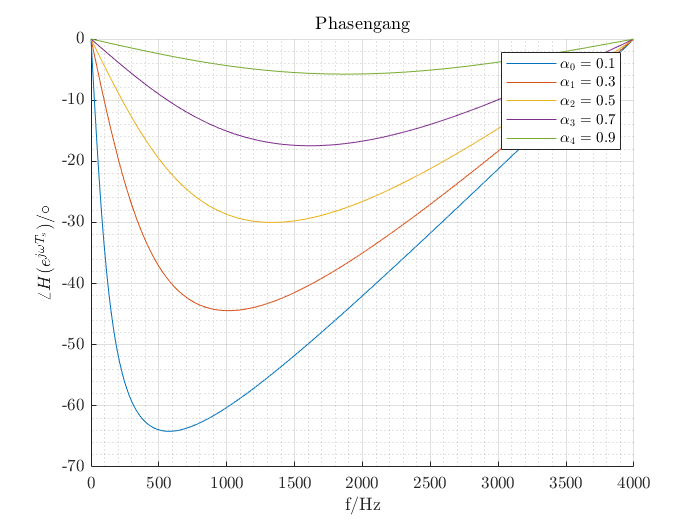

phase_0 = -1*atan(((1-alpha_0)*sin(2*pi*f*Ts))./(1-(1-alpha_0)*cos(2*pi*f*Ts)))*180/pi;
phase_1 = -1*atan(((1-alpha_1)*sin(2*pi*f*Ts))./(1-(1-alpha_1)*cos(2*pi*f*Ts)))*180/pi;
phase_2 = -1*atan(((1-alpha_2)*sin(2*pi*f*Ts))./(1-(1-alpha_2)*cos(2*pi*f*Ts)))*180/pi;
phase_3 = -1*atan(((1-alpha_3)*sin(2*pi*f*Ts))./(1-(1-alpha_3)*cos(2*pi*f*Ts)))*180/pi;
phase_4 = -1*atan(((1-alpha_4)*sin(2*pi*f*Ts))./(1-(1-alpha_4)*cos(2*pi*f*Ts)))*180/pi;

fig = figure;
set(fig,'color','w');
plot(f,phase_0);     
hold on;
plot(f,phase_1);     
hold on;
plot(f,phase_2);     
hold on;
plot(f,phase_3);     
hold on;
plot(f,phase_4);     
hold on;
grid on; grid minor;
box off;
xlabel('f/Hz','Interpreter','latex');
ylabel('$ \angle H(e^{j\omega T_s})/ {\circ} $','Interpreter','latex');
title('Phasengang','Interpreter','latex','FontWeight','Normal');
legend(['$\alpha_0 =$',' ',num2str(alpha_0)],...
       ['$\alpha_1 =$',' ',num2str(alpha_1)],...
       ['$\alpha_2 =$',' ',num2str(alpha_2)],...
       ['$\alpha_3 =$',' ',num2str(alpha_3)],...
       ['$\alpha_4 =$',' ',num2str(alpha_4)],...
       'Interpreter','latex');

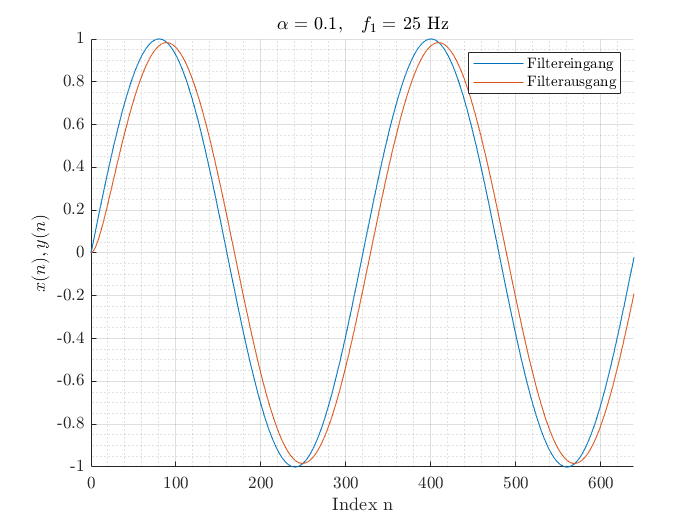

T = 1;
M = T/Ts;
n = 0:1:M-1; 

f1 = 25; 

P1 = 2*round(fs/f1);

x1 = sin(2*pi*f1*Ts*n); 
y1 = filter(num,denom,x1);

fig = figure;
set(fig,'color','w');
plot(n(1:P1),x1(1:P1));
hold on
plot(n(1:P1),y1(1:P1));
grid on; grid minor;
box off;
axis tight
xlabel('Index n','Interpreter','latex');
ylabel('$x(n), y(n)$','Interpreter','latex');
title(['$\alpha =$',' ',num2str(alpha_0),',\quad $f_1 =$',' ',num2str(f1),' Hz'],'Interpreter','latex','FontWeight','Normal');
legend('Filtereingang','Filterausgang','Interpreter','latex');

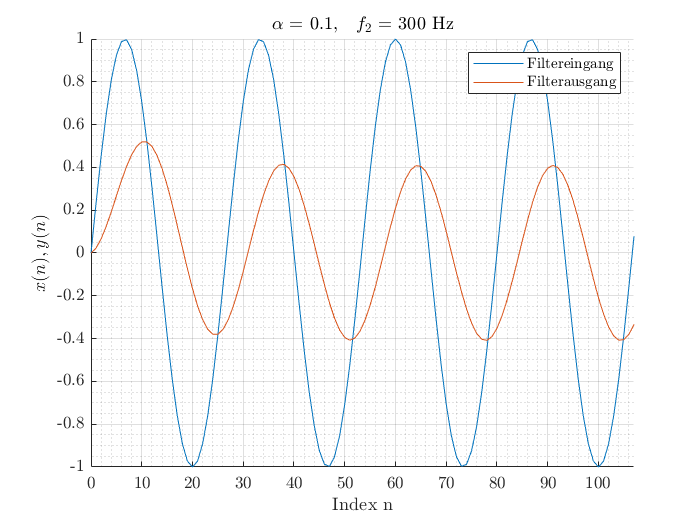

f2 = 300; 

P2 = 4*round(fs/f2);

x2 = sin(2*pi*f2*Ts*n); 
y2 = filter(num,denom,x2);

fig = figure;
set(fig,'color','w');
plot(n(1:P2),x2(1:P2));
hold on
plot(n(1:P2),y2(1:P2));
grid on; grid minor;
box off;
axis tight
xlabel('Index n','Interpreter','latex');
ylabel('$x(n), y(n)$','Interpreter','latex');
title(['$\alpha =$',' ',num2str(alpha_0),',\quad $f_2 =$',' ',num2str(f2),' Hz'],'Interpreter','latex','FontWeight','Normal');
legend('Filtereingang','Filterausgang','Interpreter','latex');

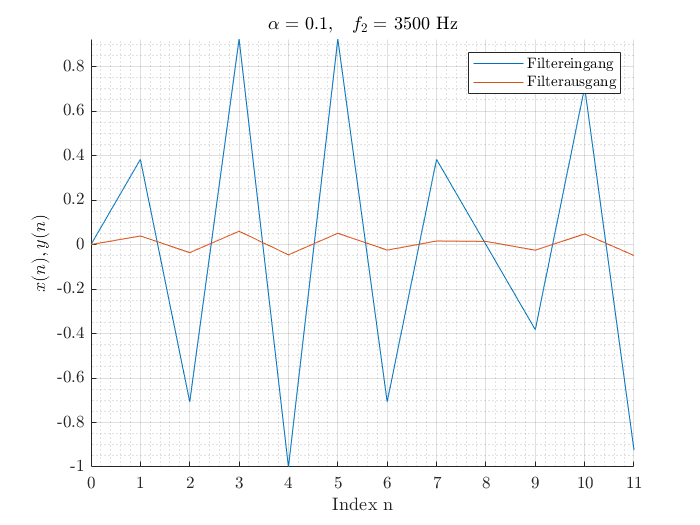

f3 = 3500; 

P3 = 6*round(fs/f3);

x3 = sin(2*pi*f3*Ts*n); 
y3 = filter(num,denom,x3);

fig = figure;
set(fig,'color','w');
plot(n(1:P3),x3(1:P3));
hold on
plot(n(1:P3),y3(1:P3));
grid on; grid minor;
box off;
axis tight
xlabel('Index n','Interpreter','latex');
ylabel('$x(n), y(n)$','Interpreter','latex');
title(['$\alpha =$',' ',num2str(alpha_0),',\quad $f_2 =$',' ',num2str(f3),' Hz'],'Interpreter','latex','FontWeight','Normal');
legend('Filtereingang','Filterausgang','Interpreter','latex');

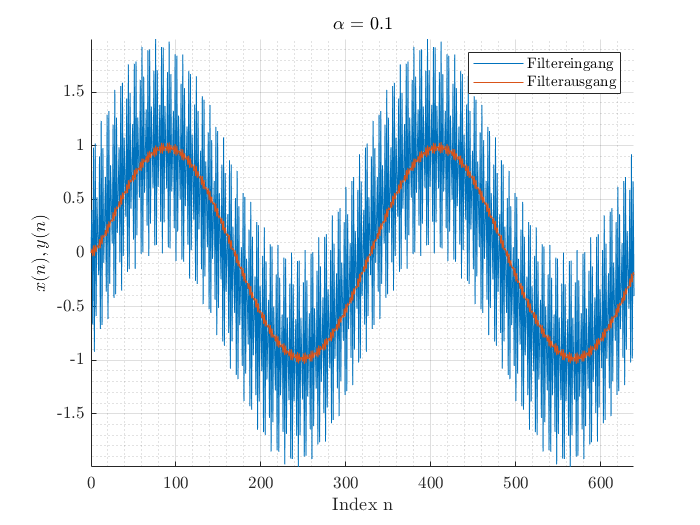

x4 = x1 + x3; 
y4 = filter(num,denom,x4);

fig = figure;
set(fig,'color','w');
plot(n(1:P1),x4(1:P1));
hold on
plot(n(1:P1),y4(1:P1));
grid on; grid minor;
box off;
axis tight
xlabel('Index n','Interpreter','latex');
ylabel('$x(n), y(n)$','Interpreter','latex');
title(['$\alpha =$',' ',num2str(alpha_0)],'Interpreter','latex','FontWeight','Normal');
legend('Filtereingang','Filterausgang','Interpreter','latex');

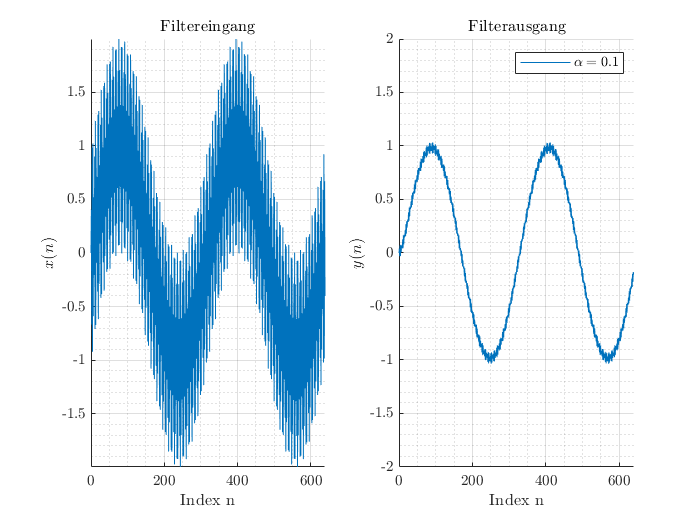

x5 = x1 + x3; 
y5  = zeros(1,length(x5));
for i = 2:length(x5)
    y5(i) = alpha*x5(i)+(1-alpha)*y5(i-1);
end

fig = figure;
set(fig,'color','w');
subplot(1,2,1)
plot(n(1:P1),x5(1:P1));
grid on; grid minor;
box off;
axis tight
xlabel('Index n','Interpreter','latex');
ylabel('$x(n)$','Interpreter','latex');
title('Filtereingang','Interpreter','latex','FontWeight','Normal');

subplot(1,2,2)
plot(n(1:P1),y5(1:P1));
grid on; grid minor;
axis([0 P1 -2 2])
box off;
xlabel('Index n','Interpreter','latex');
ylabel('$y(n)$','Interpreter','latex');
title('Filterausgang','Interpreter','latex','FontWeight','Normal');
legend(['$\alpha =$',' ',num2str(alpha_0)],'Interpreter','latex','FontWeight','Normal');